# Load and save all image data before any manipulation

%% Opening and saving file data to variables
close all;
clear variables;
clc;

addpath(genpath(pwd)); % enable access to current directory

% Read CSV file
% Col B: x-coord
% Col C: y-coord
% Col D: z-coord (distance from camera)
sky_data = xlsread('sky.csv','B:D');

% Read image files and store it in a stack

% imread() returns an image array of type uint8 or uint16
% single() turns the image to single-precision floating (32-bit)
% ./(2.^16-1) normalizes the image pixels  to vlaues [0,1]
% 
% img: 4D array of dims [height; width; channels; num_of_imgs]

% RGB version
imgs(:,:,:,1) = imread('origin.jpg');%./(2.^16-1);
imgs(:,:,:,2) = imread('a.jpg');%./(2.^16-1);
imgs(:,:,:,3) = imread('b.jpg');%./(2.^16-1);
imgs(:,:,:,4) = imread('c.jpg');%./(2.^16-1);
imgs(:,:,:,5) = imread('d.jpg');%./(2.^16-1);
imgs(:,:,:,6) = imread('e.jpg');%./(2.^16-1);

% Gray-scaled version
imgs_gray(:,:,1) = rgb2gray(imgs(:,:,:,1));
imgs_gray(:,:,2) = rgb2gray(imgs(:,:,:,2));
imgs_gray(:,:,3) = rgb2gray(imgs(:,:,:,3));
imgs_gray(:,:,4) = rgb2gray(imgs(:,:,:,4));
imgs_gray(:,:,5) = rgb2gray(imgs(:,:,:,5));
imgs_gray(:,:,6) = rgb2gray(imgs(:,:,:,6));


## Display sky.csv

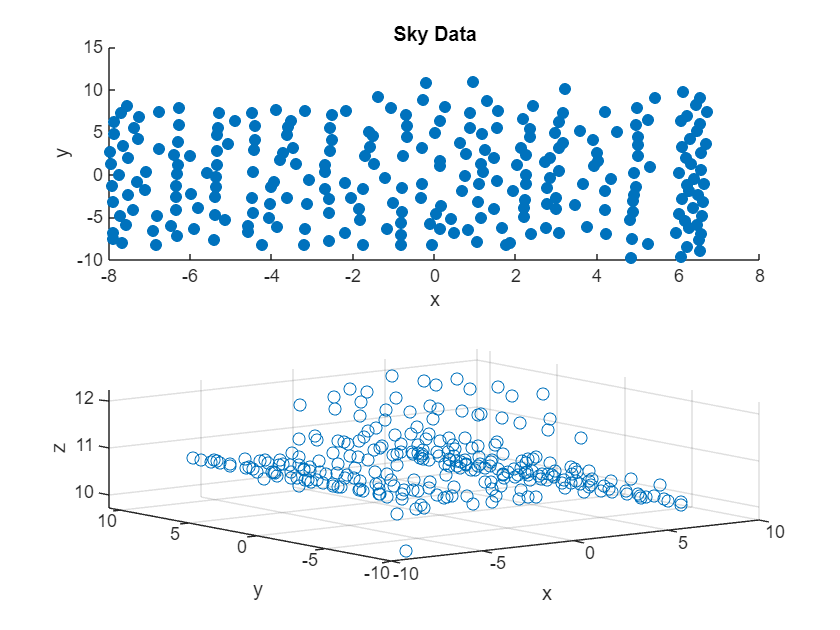

close all;

figure;
tiledlayout(2,1);

nexttile;
scatter(sky_data(:,1), sky_data(:,2),'filled'),  title('Sky Data');
xlabel('x'), ylabel('y');
nexttile;
scatter3(sky_data(:,1),sky_data(:,2),sky_data(:,3));
xlabel('x'), ylabel('y'), zlabel('z');
grid on;

## View image files

Make sure all the image file (original) was saved properly by displaying them

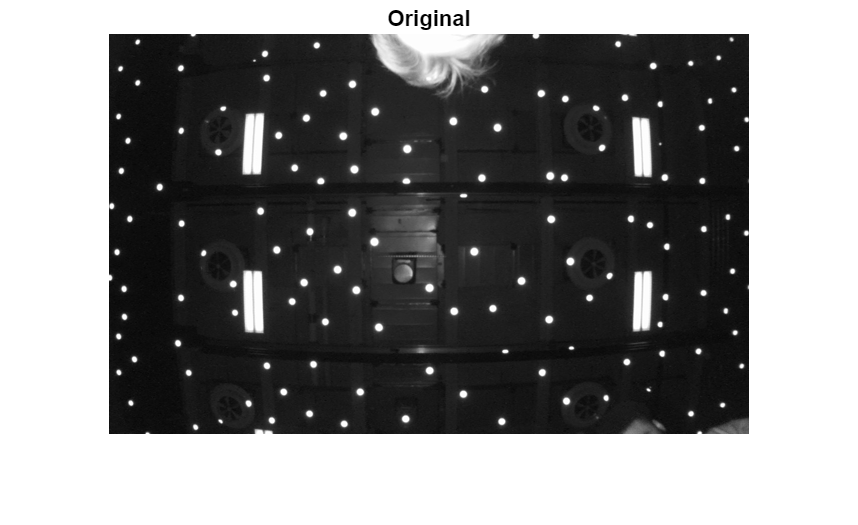

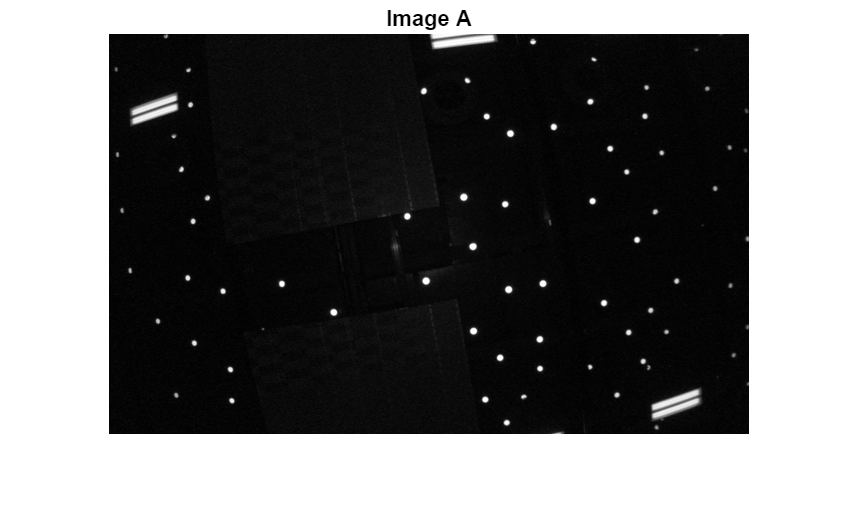

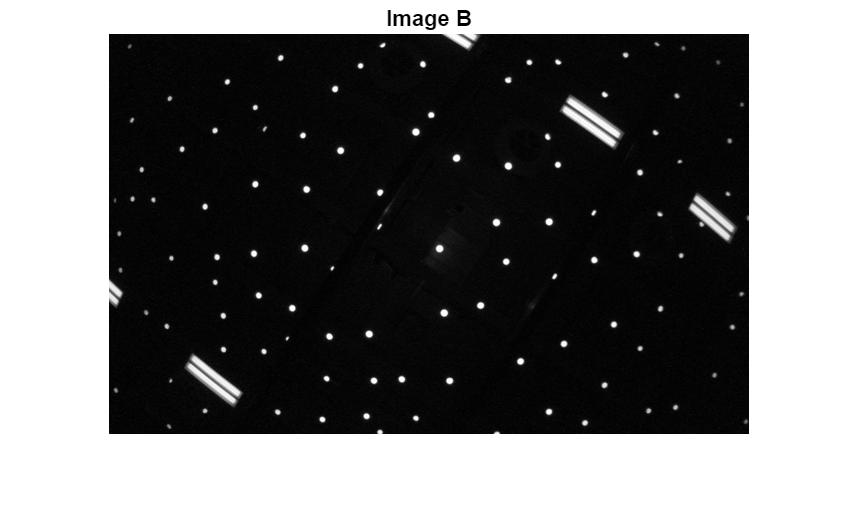

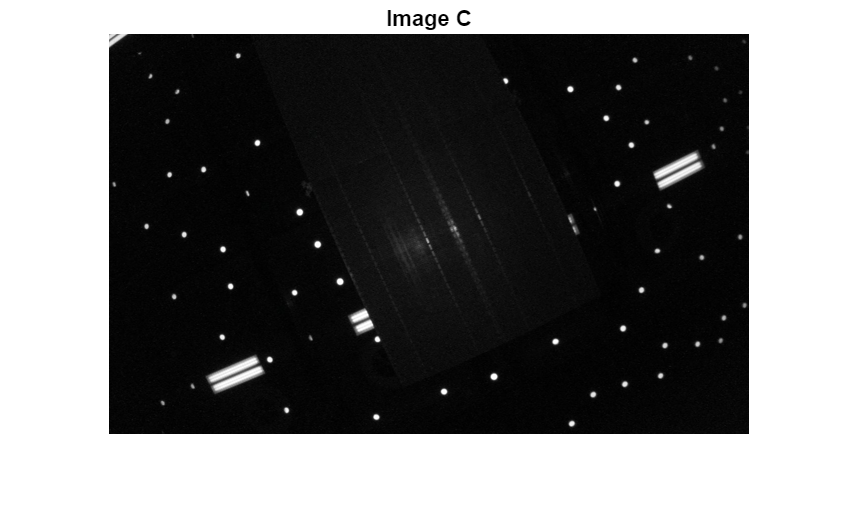

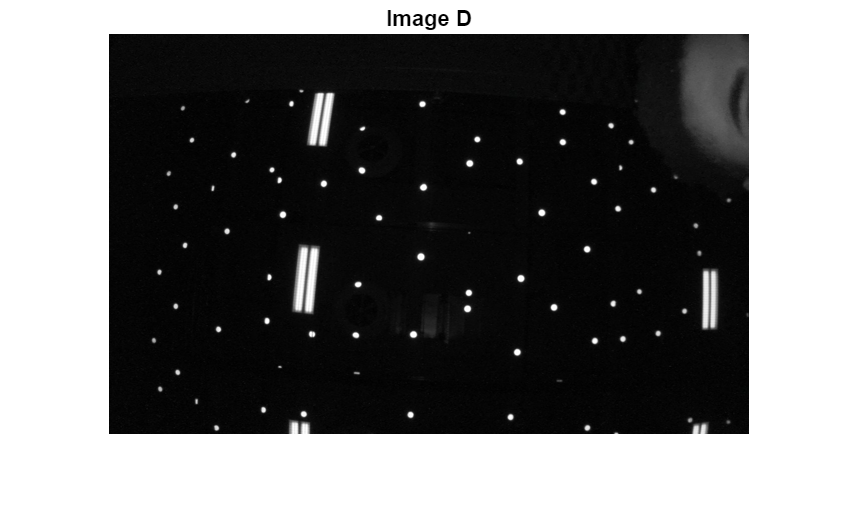

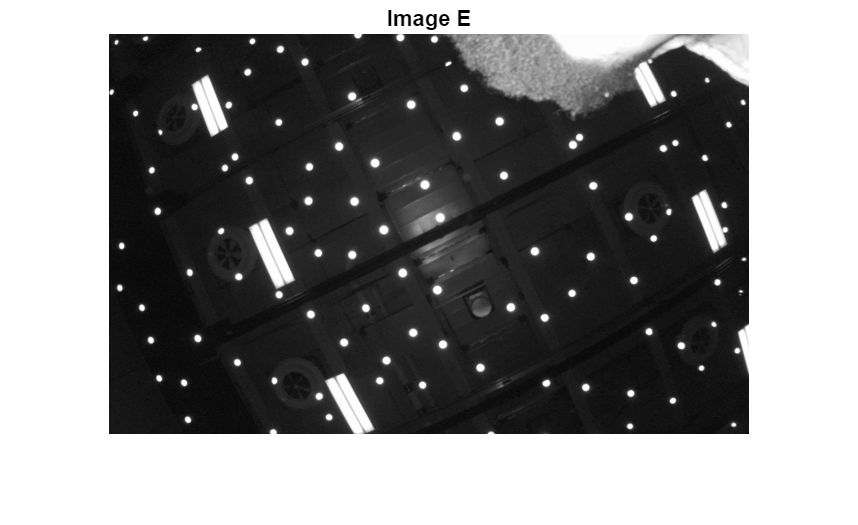

close all;

for i = 1:6
   figure;
   imshow(imresize(imgs(:,:,:,i),1/2));
   if i==1 
       title('Original'); 
   else
       curr_img = append("Image ", char(65+i-2));
       title(curr_img); 
   end
end

## Save image data into .mat file to load and use in other files

save rawdata.mat sky_data imgs_gray imgs sky_data